addpath 'E:\MATLAB'
addpath 'E:'\MATLAB\Images\
A=imread("tulips.png");
R = double(A(:,:,1)); % Red channel
G = double(A(:,:,2)); % Green channel
B = double(A(:,:,3)); % Blue channel

tic;
[LR,LRG,LRB,SR3,SR3G,SR3B]= KipkoechSuperResolution (R,G,B);
toc;

Elapsed time is 0.855092 seconds.



LRimage=cat(3,uint8(LR),uint8(LRG),uint8(LRB));
SRimage=cat(3,uint8(SR3),uint8(SR3G),uint8(SR3B));
Rssim=ssim(uint8(SR3),uint8(R))

Rssim = 0.9380

Rpsnr=psnr(uint8(SR3),uint8(R))

Rpsnr = 34.6760

Gssim=ssim(uint8(SR3G),uint8(G))

Gssim = 0.9571

Gpsnr=psnr(uint8(SR3G),uint8(G))

Gpsnr = 34.2951

Bssim=ssim(uint8(SR3B),uint8(B))

Bssim = 0.9530

Bpsnr=psnr(uint8(SR3B),uint8(B))

Bpsnr = 33.7780

ssim(A,SRimage)

ans = 0.9841

psnr(A,SRimage)

ans = 34.2341

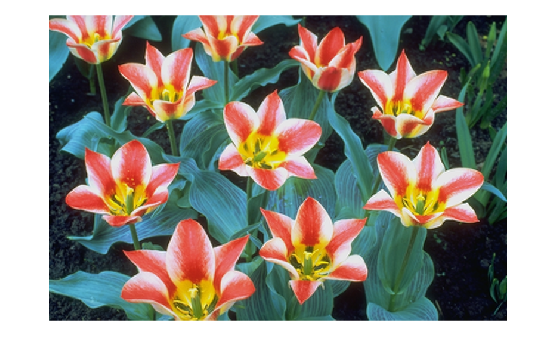

imshow(uint8(SRimage))

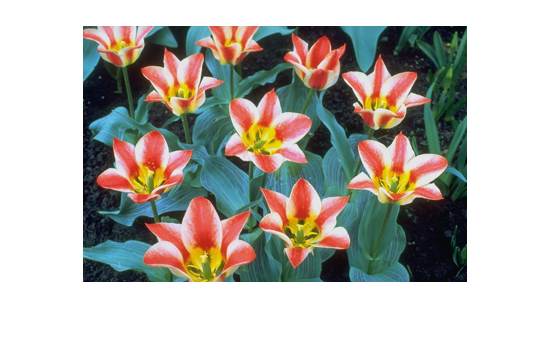

imshow(uint8(LRimage))

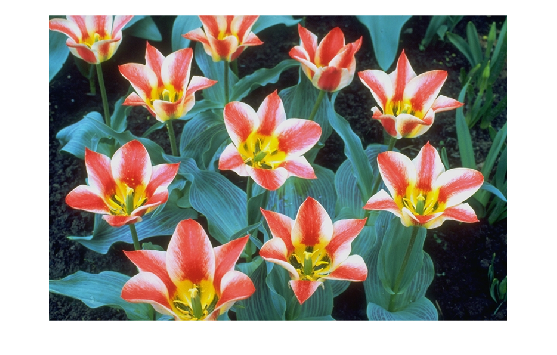

imshow(uint8(A))


%imwrite(SRimage,'E:\MATLAB\IMAGE SETS\SR_testing_datasets\results\monarchproposed.png')
%imwrite(LRimage,'E:\MATLAB\IMAGE SETS\SR_testing_datasets\results\babyLR.png')

function [LR,LRG,LRB,SR3,SR3G,SR3B]= KipkoechSuperResolution (R,G,B)
k=2;
LR=KipkoechDownSampling(R,k);
LRG=KipkoechDownSampling(G,k);
LRB=KipkoechDownSampling(B,k);
LRPrefiltered=KipkoechCubicBSplinesPrefilter(LR);
LRGPrefiltered=KipkoechCubicBSplinesPrefilter(LRG);
LRBPrefiltered=KipkoechCubicBSplinesPrefilter(LRB);
InterpolatedImageR=KipkoechBSplinesInterpolation(LRPrefiltered,k);
InterpolatedImageG=KipkoechBSplinesInterpolation(LRGPrefiltered,k);
InterpolatedImageB=KipkoechBSplinesInterpolation(LRBPrefiltered,k);
SRinitialR=KipkoechDWT(InterpolatedImageR,R);
SRinitialG=KipkoechDWT(InterpolatedImageG,G);
SRinitialB=KipkoechDWT(InterpolatedImageB,B);
% Downsample SR
LR1=KipkoechDownSampling(SRinitialR,k);
LR1G=KipkoechDownSampling(SRinitialG,k);
LR1B=KipkoechDownSampling(SRinitialB,k);
[M,N]=size(LR1);
HF=zeros(M,N);
%Back Projection Step 1
E1=LR-LR1;
E1G=LRG-LR1G;
E1B=LRB-LR1B;
E1i=weightedguidedfilter(E1,E1,7,2);
E1iG=weightedguidedfilter(E1G,E1G,7,2);
E1iB=weightedguidedfilter(E1B,E1B,7,2);
E11=double(E1i).*2;
E11G=double(E1iG).*2;
E11B=double(E1iB).*2;
BP1=idwt2(E11,HF,HF,HF,'db1');
BP1G=idwt2(E11G,HF,HF,HF,'db1');
BP1B=idwt2(E11B,HF,HF,HF,'db1');
SR1=SRinitialR+BP1;
SR1G=SRinitialG+BP1G;
SR1B=SRinitialB+BP1B;
% Back Projection Step 2
LR2=KipkoechDownSampling(SR1,k);
LR2G=KipkoechDownSampling(SR1G,k);
LR2B=KipkoechDownSampling(SR1B,k);
E2=LR-LR2;
E2G=LRG-LR2G;
E2B=LRB-LR2B;
E2i=weightedguidedfilter(E2,E2,7,2);
E2iG=weightedguidedfilter(E2G,E2G,7,2);
E2iB=weightedguidedfilter(E2B,E2B,7,2);
E22=double(E2i).*2;
E22G=double(E2iG).*2;
E22B=double(E2iB).*2;
BP2=idwt2(E22,HF,HF,HF,'db1');
BP2G=idwt2(E22G,HF,HF,HF,'db1');
BP2B=idwt2(E22B,HF,HF,HF,'db1');
SR2=SR1+BP2;
SR2G=SR1G+BP2G;
SR2B=SR1B+BP2B;
% Back Projection Step 3
LR3=KipkoechDownSampling(SR2,k);
LR3G=KipkoechDownSampling(SR2G,k);
LR3B=KipkoechDownSampling(SR2B,k);
E3=LR-LR3;
E3G=LRG-LR3G;
E3B=LRB-LR3B;
E3i=weightedguidedfilter(E3,E3,7,2);
E3iG=weightedguidedfilter(E3G,E3G,7,2);
E3iB=weightedguidedfilter(E3B,E3B,7,2);
E33=double(E3i).*2;
E33G=double(E3iG).*2;
E33B=double(E3iB).*2;
BP3=idwt2(E33,HF,HF,HF,'db1');
BP3G=idwt2(E33G,HF,HF,HF,'db1');
BP3B=idwt2(E33B,HF,HF,HF,'db1');
SR3=SR2+BP3;
SR3G=SR2G+BP3G;
SR3B=SR2B+BP3B;
end
